# Team 3: Hexapod Robot Leg Inverse Kinematics

#### Gary Encinas, Justin Fossum, Jason Munger, and Mithulesh Ramkumar

## Building The Model

The hexapod robot can initially be lookoed at as each leg being it's own RRR type robot which we can build the kinematic model for.

### The Basics

We know that we want our robot to have a three revolute joints and would have a basic diagram as shown in Fig. 1.

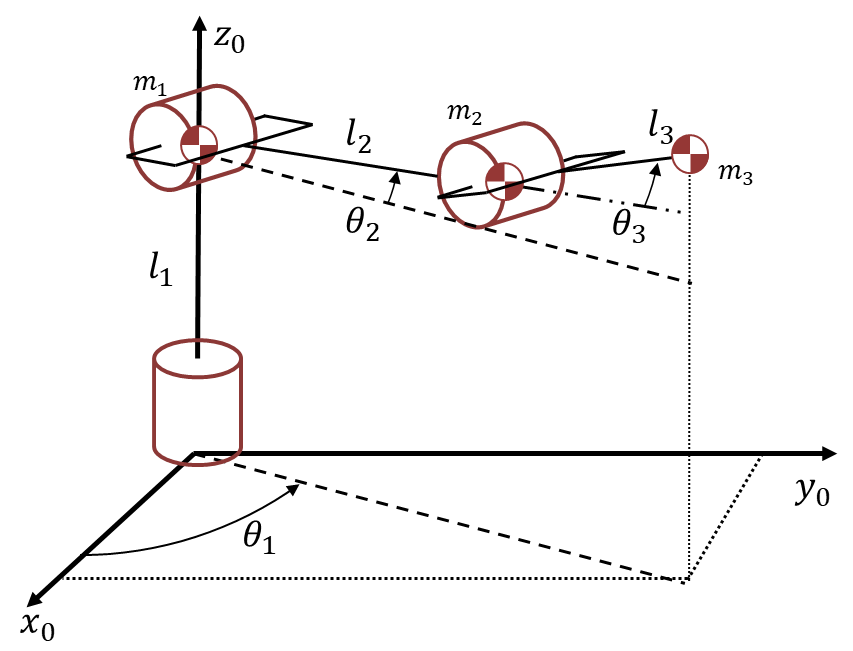

**Figure 1: Hexapod Leg RRR Robot layout model.**

From this layout we can also easily determine our Denavit-Hartenberg (DH) parameters as shown in Table 1.

**Table 1: Hexapod Leg RRR Robot DH parameters.**

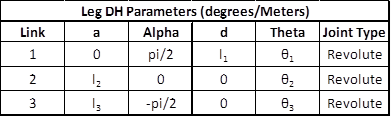

### Simple Forward Kinematics For Double Check

First, we should remove items from workspace, freeing up system memory, and clear current command window.

%clf('reset'); %Clear current figure window
clear; % Remove items from workspace, freeing up system memory
% clc; % Clear current command window

#### Setting Robot Variables

The equations for the transformation matricies were taken as snippets from the code found in the "Hexapo_Robot_Leg_dynamics.mlx" file.

l1 = 1e-12; % Link one length i nmm
l2 = 640; % Link two length in mm
l3 = 960; % Link three length in mm

prompt = {'Theta 1 [degrees]:','Theta 3 [degrees]:','Theta 3 [degrees]:'};
dlgtitle = 'Desired Robot Configuration';
dims = [1 60];
definput = {'0','16.256','-82.575'};
user_input = inputdlg(prompt,dlgtitle,dims,definput);

if size(user_input) == 0
    disp('User closed out of Desired Robot Configuration input. Using default values [0 16.256 -93.789]')
    user_input = definput;
end

joints = [str2double(user_input(1)); str2double(user_input(2)); str2double(user_input(3))];
q1 = deg2rad(joints(1));
q2 = deg2rad(joints(2));
q3 = deg2rad(joints(3));

T1 = [cos(q1), 0,  sin(q1),   0;
      sin(q1), 0, -cos(q1),   0;
      0,       1,        0,  l1;
      0,       0,        0,   1];

T2 = [cos(q1)*cos(q2), -cos(q1)*sin(q2),  sin(q1), l2*cos(q1)*cos(q2);
      cos(q2)*sin(q1), -sin(q1)*sin(q2), -cos(q1), l2*cos(q2)*sin(q1);
      sin(q2),                  cos(q2),        0,    l1 + l2*sin(q2);
      0,                              0,        0,                  1];

T3 = [cos(q1)*cos(q2)*cos(q3) - cos(q1)*sin(q2)*sin(q3), -sin(q1), - cos(q1)*cos(q2)*sin(q3) - cos(q1)*cos(q3)*sin(q2), l2*cos(q1)*cos(q2) + l3*cos(q1)*cos(q2)*cos(q3) - l3*cos(q1)*sin(q2)*sin(q3);
      cos(q2)*cos(q3)*sin(q1) - sin(q1)*sin(q2)*sin(q3),  cos(q1), - cos(q2)*sin(q1)*sin(q3) - cos(q3)*sin(q1)*sin(q2), l2*cos(q2)*sin(q1) + l3*cos(q2)*cos(q3)*sin(q1) - l3*sin(q1)*sin(q2)*sin(q3);
                      cos(q2)*sin(q3) + cos(q3)*sin(q2),        0,                   cos(q2)*cos(q3) - sin(q2)*sin(q3),                    l1 + l2*sin(q2) + l3*cos(q2)*sin(q3) + l3*cos(q3)*sin(q2);
                                                      0,        0,                                                   0,                                                                            1];

EE_position = T3(1:3,4)

EE_position =   773.2124
  178.4348
 -352.2247


Now we can work on our inverse model.

### Inverse Kinematic Model Method One - Geometric

We can see that from the XY Plane, the desired leg position for $\theta_1$ from the origin of that leg is determined by the diagram shown in Fig 2.

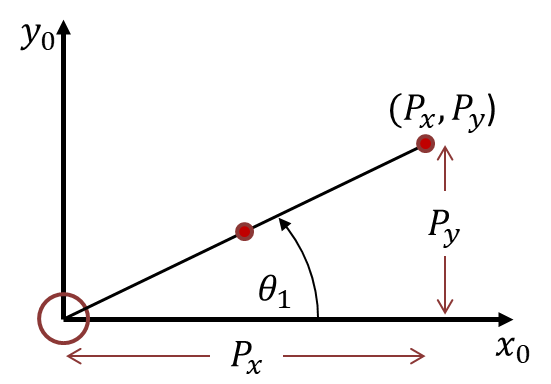

**Figure 2: RRR Robot model on XY Plane.**

#### Finding Theta 1

Fig. 2 shows that solving for $\theta_1$ is simple where $\tan \left(\theta_1 \right)=\frac{P_y }{P_x }$ such that $\theta_1 =\tan^{-1} \left(\frac{P_y }{P_x }\right)$. For a more complete determination of $\theta_1$, we can utilize the four-quadrant inverse tangent $\textrm{atan2}\left(y,x\right)$ which would provide an answer from [0, $2\pi$). For our individual leg and our full robot model, we know that the leg will never rotate more than $\pm \frac{\pi }{2}$ as it would hit the robot main body or another leg, so we can leave our solution as $\theta_1 =\tan^{-1} \left(\frac{P_y }{P_x }\right)$.

theta1_meathod1 = atan(EE_position(2)/EE_position(1)); % The method we will likly use
theta1_meathod2 = atan2(EE_position(2),EE_position(1)); % The arctan2 method

if round(theta1_meathod1, 4) == round(q1, 4)
    disp("Finding Theta 1 with method one works!")
elseif round(theta1_meathod2, 4) == round(q1, 4)
    disp("Finding Theta 1 with method two works!")
end

Finding Theta 1 with method one works!


#### Finding Theta 3

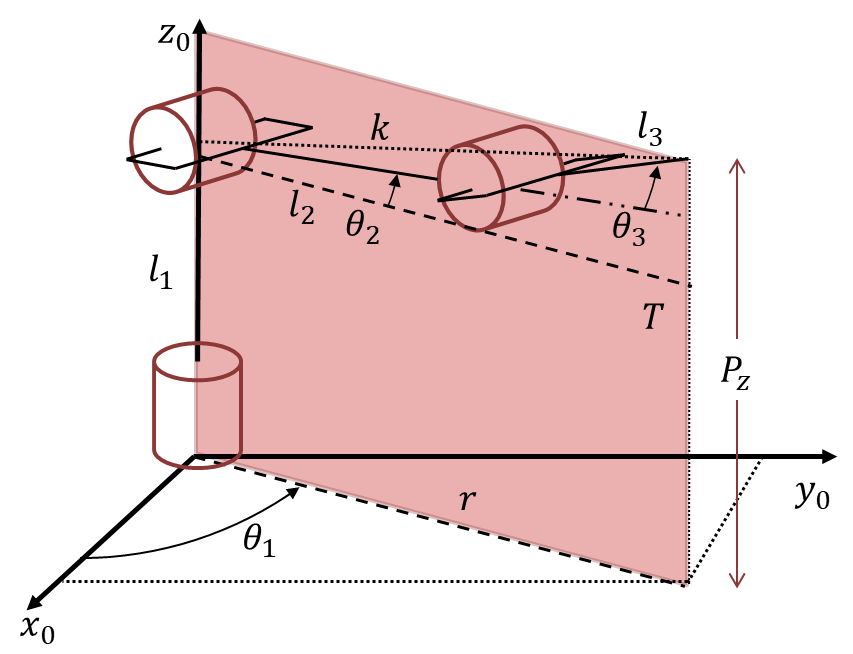

**Figure 3: RRR Robot model on TZ Plane.**

Now that we know the angle of $\theta_1$ we can make a plane $T$ that is defined by the angle of $\theta_1$ and the height in the $Z$direction, defined in Fig. 3 as $P_z$. The point of $x$ and $y$ have also provided us with a means to calculate $r$ such that $r=\sqrt{P_x^2 +P_y^2 }$. We also have the new line $k$ which goes from the origin of joint 2 to the end-effector (EE). We can find $k$ by recognizing that


$$k=\sqrt{{\left(P_z -l_1 \right)}^2 +r^2 }$$


Now we can use the law of cosines to find the angle of $\theta_3$. The law of cosines yields the equation


$$\cos \left(\theta_3 \right)=\frac{k^2 -l_2^2 -l_3^2 }{2l_2 l_3 }$$


which we can call variable $D$ making it easier for us to write $\theta_3$ as $\theta_3 =\cos^{-1} \left(D\right)$. This leads to noticing that if $\cos \left(\theta_3 \right)$ is given by $D$, then $\sin \left(\theta_3 \right)$ is given by


$$\sin \left(\theta_3 \right)=\pm \sqrt{1-D^2 }$$


meaning a better way to find $\theta_3$ is defined as


$$\theta_3 =\tan^{-1} \frac{\pm \sqrt{1-D^2 }}{D}$$


Defining $\theta_3$ as above leads to the advantage of finding both the ankle-up and ankle-down solutions by choosing the negative and positive sings in the arctangent equation directly above.

For the hexapod robot, the majority of the leg configurations will be with the ankle up meaning link 3 rotation in a negative fashion relative to its home configuration. As such, we will primarily use the negative squareroot of the arctangent.

r = sqrt(EE_position(1)^2+EE_position(2)^2);
k = sqrt((EE_position(3)-l1)^2+r^2);
D = (k^2-l2^2-l3^2)/(2*l2*l3);
theta3_D = acos(D);
theta3_ankleup = atan((-sqrt(1-D^2))/D);
theta3_ankledown = atan((+sqrt(1-D^2))/D);

if round(theta3_ankleup, 4) == round(q3, 4)
    disp("Finding Theta 3 with ankle up works!")
elseif round(theta3_ankledown,4) == round(q3, 4)
    disp("Finding Theta 3 with ankle down works!")
elseif round(-abs(theta3_D), 4) == round(q3, 4)
    disp("Finding Theta 3 with law of cosines assuming always negative works!")
elseif round(theta3_D, 4) == round(q3, 4)
    disp("Finding Theta 3 with law of cosines as is works!")
end

Finding Theta 3 with law of cosines assuming always negative works!


#### Finding Theta 2

### 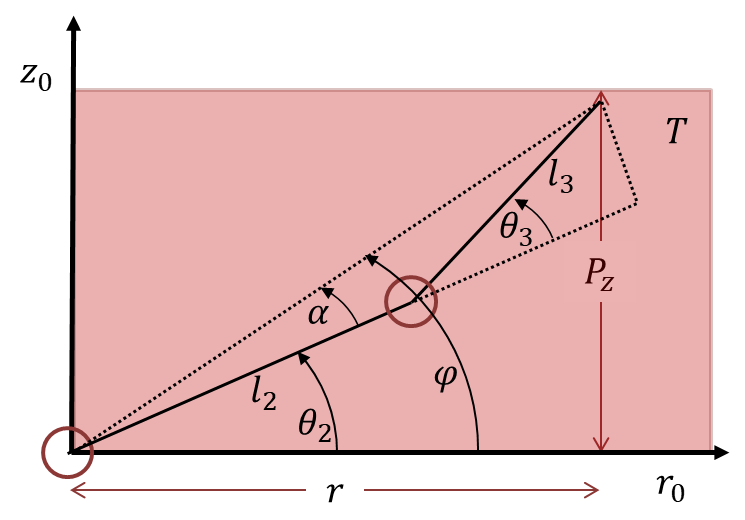

**Figure 4: RRR Robot model on detailed TZ Plane.**

We can see fom Fig. 4 that $\theta_2 =\phi -\alpha$. We can also see that $\phi =\tan^{-1} \left(\frac{P_z }{r}\right)$ as the line from the base of link 2 leading to the tip of link 3 is the hypotenuse of a triangle formed with the other sides being $r$ and $P_z$. Another similar triangle can be made from the same  hypotenuse, the length of ink two plus the length $l_3 \cdot \cos \left(\theta_3 \right)$, and then the last side is made of $l_3 \cdot \sin \left(\theta_3 \right)$. We can use these same sides to determine the angle of $\alpha$ just as we had done with $\phi$. This leaves us with $\alpha =\tan^{-1} \left(\frac{l_3 \cdot \sin \left(\theta_3 \right)}{l_2 +l_3 \cdot \cos \left(\theta_3 \right)}\right)$. Putting both od these together we can see that $\theta_2 =\tan^{-1} \left(\frac{P_z }{r}\right)-\tan^{-1} \left(\frac{l_3 \cdot \sin \left(\theta_3 \right)}{l_2 +l_3 \cdot \cos \left(\theta_3 \right)}\right)$.

phi_u = atan(EE_position(3)/r);
alpha_u = atan((l3*sin(theta3_ankleup))/(l2+l3*cos(theta3_ankleup)));
theta_2_u = phi_u - alpha_u;
phi_d = atan(EE_position(3)/r);
alpha_d = atan((l3*sin(theta3_ankledown))/(l2+l3*cos(theta3_ankledown)));
theta_2_d = phi_d - alpha_d;
if round(theta_2_u,4) == round(q2, 4)
    disp("Finding Theta 2 with ankle up works!")
elseif round(theta_2_d,4) == round(q2, 4)
    disp("Finding Theta 2 with ankle down works!")
end

### Inverse Kinematic Model Method Two - Loop Closures

We can see from running the code a few times with different values, the ankle configuration of the leg might change and the exact method of finding the joint angles will also change. The second method of finding the correct leg joint positions is reliant on loop closures and vector math. No matter the joint angles, this method will always provide a corresponding result while being computationally less intense than the Geometric method. Due to being computationally light, we can actually use this method to calculute all legs simultaneously.

There are some initial assumptions/givens that need to be made/determined before we can move forward with this approach. We need to know the designed distribution of the legs along the body of the robot, we need to know the designed radius of the robot body (where the hip joint connects), the assumed leg ground contact radius, and an assumed body pose made up of the assumed $X$ and $Y$ positions of the robot, the nominal ground clearance ($Z$), and Euler angles of rotation about the world frame assumed to be $a$, $b$, $c$ combined to provide a pose vector $\vec{P} =\left\lbrack \begin{array}{cccccc}
x & y & z & a & b & c
\end{array}\right\rbrack$. This vector can be thought of as a row vector or a column vector.

P = [0,0,500,0,0,0]'; % Desired robot Pose in mm and degrees

Fp = 1625; % Fixed platform radius in mm
Mp = 625; % Moving platform radius in mm
radial = 60*pi/180; % Distribution of legs around the hexapod

alpha = zeros(1,6); % Initilaizing the hip joint variable
beta = zeros(1,6); % Initilaizing the knee joint variable
gamma = zeros(1,6); % Initilaizing the ankle joint variable
rho = zeros(1,6); % Initilaizing rho variable
phi = zeros(1,6); % Initilaizing phi variable
L = zeros(3,6); % Initilaizing the leg vectors matrix
L_prime = zeros(3,6); % Initilaizing the leg prim vectors matrix
l_prime = zeros(3,6); % Initilaizing the normalized leg prim vectors matrix

% Pull out Position and Euler Angle information from the desired pose
o = P(1:3,1); % Moving platform local frame origin
a = P(4)*pi/180; % First Euler angle representation
b = P(5)*pi/180; % Second Euler angle representation
c = P(6)*pi/180; % Third Euler angle representation

% Calculate the Rotarion Matrix
R = Euler('xyz',a,b,c);

% Calculate upper joint positions with respect to the upper coordinate
% frame
s1 = [Mp*cos(2*radial), Mp*sin(2*radial), 0]';
s2 = [Mp*cos(1*radial), Mp*sin(1*radial), 0]';
s3 = [Mp*cos(3*radial), Mp*sin(3*radial), 0]';
s4 = [Mp*cos(0*radial), Mp*sin(0*radial), 0]';
s5 = [Mp*cos(4*radial), Mp*sin(4*radial), 0]';
s6 = [Mp*cos(5*radial), Mp*sin(5*radial), 0]';

s = [s1 s2 s3 s4 s5 s6];

% Calculate lower joint positions with respect to the lower corrdinate
% frame
u1 = [Fp*cos(2*radial), Fp*sin(2*radial), 0]';
u2 = [Fp*cos(1*radial), Fp*sin(1*radial), 0]';
u3 = [Fp*cos(3*radial), Fp*sin(3*radial), 0]';
u4 = [Fp*cos(0*radial), Fp*sin(0*radial), 0]';
u5 = [Fp*cos(4*radial), Fp*sin(4*radial), 0]';
u6 = [Fp*cos(5*radial), Fp*sin(5*radial), 0]';

u = [u1 u2 u3 u4 u5 u6];

#### Deriving the First Loop Closure

#### 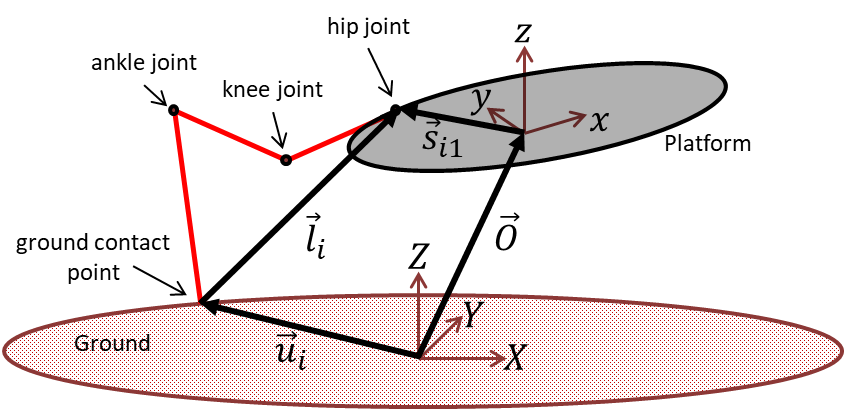

**Figure 5: Hexapod robot first loop closure diagram.**

In the previous method, we were referring to each of the leg joints as $\theta_i$ when typically the leg angles are referred to as $\alpha$, $\beta$, and $\gamma$ for the hip, knee, and ankle respectively. As such, we will use the joint angles as $\alpha$, $\beta$, and $\gamma$ for this method.

As detailed in Fig. 5, we can see that


$${\vec{l} }_i =\vec{O} +R{\vec{s} }_{\mathrm{i1}} -{\vec{u} }_i$$


Now, the direction that $l_i$ points outside of the plane formed between the hip joint and the ground contact is the desired angle of $\alpha$ for that leg. This can be calculated as


$$\alpha =\tan^{-1} \left(\frac{l_{i,Y} }{l_{i,X} }\right)$$


for i =1:6
    L(:,i) = o + R * s(:,i) - u(:,i); % Leg vector
    alpha(i) = atan(L(2,i)/L(1,i));
end

#### Deriving the Second Loop Closure

#### 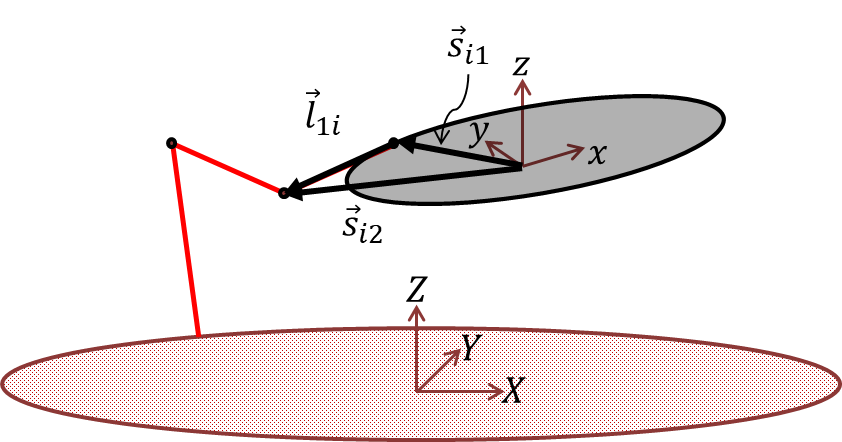

**Figure 6: Hexapod robot second loop closure diagram.**

With the direction of ${\vec{l} }_i$ known, we can build an intermediary loop closure seen in Fig. 6 that does not immediately find another joint angle but is used for further calculations. This second loop provides us with


$${\vec{s} }_{\mathrm{i2}} ={\vec{s} }_{\mathrm{i1}} +{\vec{l} }_{1i}$$


which can be defined in more detail as


$${\vec{s} }_{\mathrm{i2}} =\left\lbrack \begin{array}{c}
s_{1\mathrm{ix}} +{\left(-1\right)}^i \cdot l_{1i} \cdot \cos \left(\alpha \right)\\
s_{1\mathrm{iy}} +{\left(-1\right)}^i \cdot l_{1i} \cdot \sin \left(\alpha \right)\\
s_{\mathrm{i1z}} 
\end{array}\right\rbrack$$


for i =1:6
    s2(:,i) = [s(1,i)+(-1)^i*l1*cos(alpha(i)); s(2,i)+(-1)^i*l1*sin(alpha(i)); s(3,i)];
end

#### Deriving the Third Loop Closure

#### 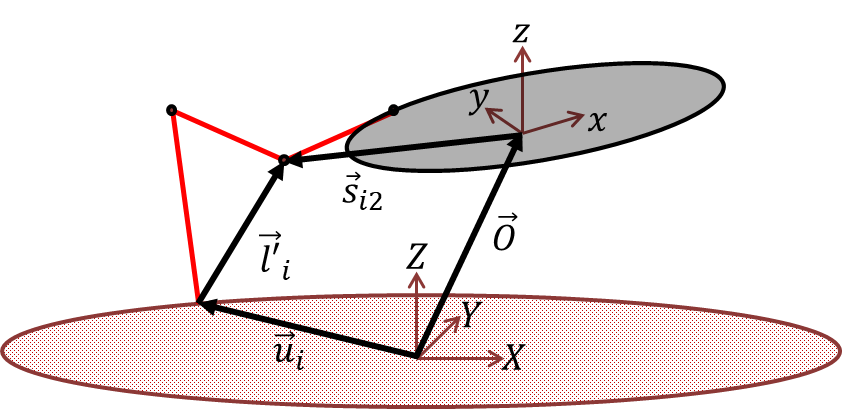

**Figure 7: Hexapod robot third loop closure diagram.**

The new vector ${\vec{s} }_{\mathrm{i2}}$ can be used to build the third loop closure as seen in Fig. 7 in order to find ${\vec{l\prime } }_i$ where


$${\vec{l\prime } }_i =\vec{O} +R{\vec{s} }_{\mathrm{i2}} -{\vec{u} }_i$$


Once again, there is not much to immediately do with ${\vec{l\prime } }_i$ to solve for the remaining unknown joint angles, but we can use it to build the fourth and final loop closure.

#### Deriving the Fourth Loop Closure and Deriving the Knee and Ankle Angles

#### 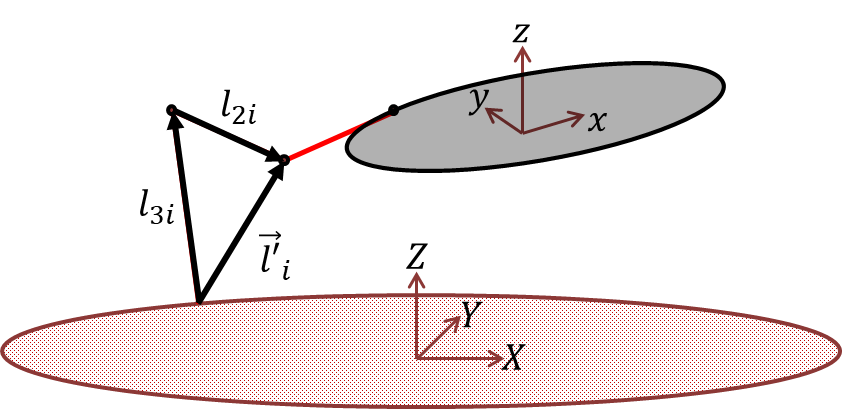

**Figure 8: Hexapod robot fourth loop closure diagram.**

The fourth loop closure is shown in Fig. 8, and it can be seen that this loop closure can be used with the law of cosines to give us


$$c^2 =a^2 +b^2 -2\cdot a\cdot b\cdot \cos \left(\gamma \right)$$


To finalize the last two joint angles, we can build all the known vectors onto a single plane as seen in Fig. 9.

#### 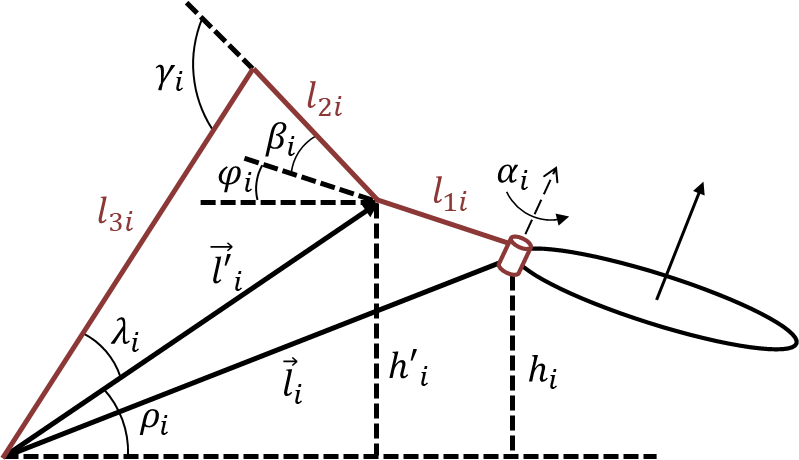

**Figure 9: Hexapod robot knee and ankle angle calculations diagram.**

All of the vectors together allow for the identification of new angles, $\lambda$, $\rho$, and $\varphi$. It can also be seen why the assumption was made to make $l_1$ a very small value rather than zero. If $l_1$ was zero, $\vec{l_i^{\prime } }$ and $\vec{l_i }$ would be the same vector.

We can start finding the last two angles by defining $\varphi$ as


$$\varphi_i =\sin^{-1} \left(\frac{{h\prime }_i -h_i }{l_{1i} }\right)\equiv \sin^{-1} \left(\frac{l\prime_{i,Z} -l_{i,Z} }{l_{1i} }\right)$$


Followed by defining $\rho$ as


$$\rho_i =\tan^{-1} \left(\frac{h\prime_i }{\sqrt{l\prime_{i,X}^2 +l\prime_{i,Y}^2 }}\right)\equiv \tan^{-1} \left(\frac{l\prime_{i,Z} }{\sqrt{l\prime_{i,X}^2 +l\prime_{i,Y}^2 }}\right)$$


By again using the law of cosines, we can see that


$$\cos \left(\pi -\gamma_i \right)=\frac{l_{2i}^2 +l_{3i}^2 -{l\prime_i }^2 }{2l_{2i} l_{3i} }$$


and that


$$\cos \left(\rho_i +\varphi_i +\beta_i \right)=\frac{{l_{\mathrm{i2}} }^2 +{{l\prime }_i }^2 -{l_{\mathrm{i3}} }^2 }{2l_{\mathrm{i2}} {l\prime }_i }$$



$$\beta_i =\cos^{-1} \left(\frac{{l_{\textrm{i2}} }^2 +{{l\prime }_i }^2 -{l_{\textrm{i3}} }^2 }{2l_{\textrm{i2}} {l\prime }_i }\right)-\left(\rho_i +\varphi_i \right)$$



$$\gamma_i =\pi -\cos^{-1} \left(\frac{l_{2i}^2 +l_{3i}^2 -{l\prime_i }^2 }{2l_{2i} l_{3i} }\right)$$


for i =1:6
    L_prime(:,i) = o + R * s2(:,i) - u(:,i); % Coxa tip vector
    l_prime(i) = norm(L_prime(:,i),2); % Coxa tip vector length (magnitude)
end

for i =1:6
    rho(i) = atan(L_prime(3,i)/(sqrt(L_prime(1,i)^2 + L_prime(2,i)^2)));
    phi(i) = asin((L_prime(3,i)-L(3,i))/l1);
    beta(i) = acos((l2^2+l_prime(i)^2-l3^2)/(2*l2*l_prime(i)))-(rho(i) + phi(i));
    gamma(i) = pi-acos((l2^2+l3^2-l_prime(i)^2)/(2*l2*l3));
end

alpha = alpha + deg2rad([60 -60 0 0 -60 60]); % Normalize the alpha angles
joint_angles_deg = horzcat([1 2 3 4 5 6]',rad2deg([alpha' beta' gamma']));
var_names = {'Leg No.', 'alpha_{i}', 'beta_{i}', 'gamma_{i}'}; % Create column names
T_joint_angles = table(joint_angles_deg(:,1),joint_angles_deg(:,2),joint_angles_deg(:,3),joint_angles_deg(:,4), 'VariableNames',var_names); % Create table object 
disp(T_joint_angles)

    Leg No.     alpha_{i}     beta_{i}    gamma_{i}
    _______    ___________    ________    _________

       1       -2.5444e-14     32.391      93.789  
       2       -1.2722e-14     32.391      93.789  
       3       -7.0167e-15     32.391      93.789  
       4                 0     32.391      93.789  
       5       -1.2722e-14     32.391      93.789  
       6       -6.3611e-14     32.391      93.789  



## Appendix

function Rotation_Matrix = Euler(type, a, b, c)
    type = lower(type);
    axis1 = char(type(1)); % Parse the first Euler angle axis
    axis2 = char(type(2)); % Parse the second Euler angle axis
    axis3 = char(type(3)); % Parse the third Euler angle axis
    R1 = Rotation(axis1,a); % Calculate the first basic rotation matrix
    R2 = Rotation(axis2,b); % Calculate the second basic rotation matrix
    R3 = Rotation(axis3,c); % Calculate the third basic rotation matrix
    
    Rotation_Matrix = R1*R2*R3; % Calculate the returning rotation matirx
end

function r = Rotation(axis, angle)
    if axis == 'x'
        r = [1 0 0;0 cos(angle) -sin(angle);0 sin(angle) cos(angle)];
    elseif axis == 'y'
        r = [cos(angle) 0 sin(angle);0 1 0;-sin(angle) 0 cos(angle)];
    elseif axis == 'z'
        r = [cos(angle) -sin(angle) 0;sin(angle) cos(angle) 0;0 0 1];
    else
        error('Rotation axis is not x, y, or z');
    end
end